**Giordano Dylan - Martelet Curtis                            M1 EEA Grp C**

# Rapport TP2: Onduleur à commande MLI

## 1/ Hacheur 4 Quadrants

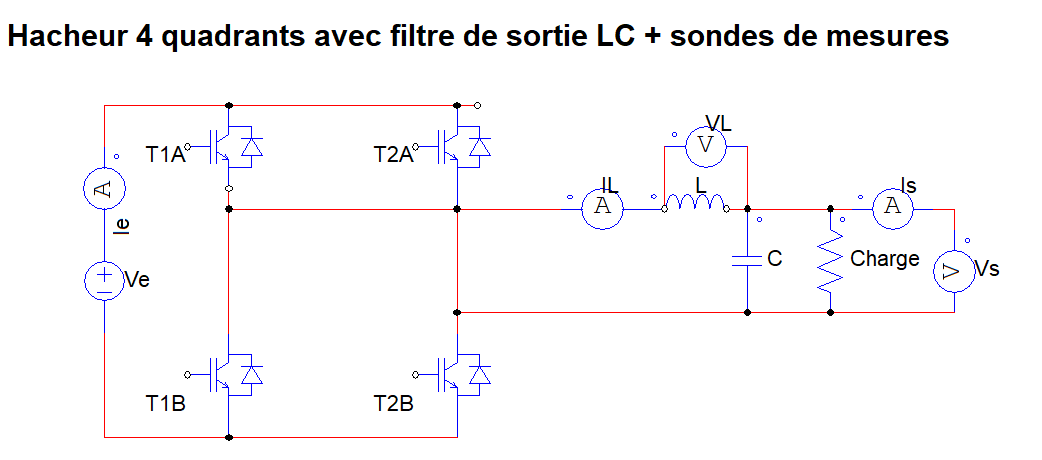

Afin d'avoir une puissance de sortie Ps de 240W, nous devons régler la charge R a 15$\Omega$.

R=$\frac{{\textrm{Vs}}^2 }{\textrm{Ps}}$=$\frac{{60}^2 }{240}$=15$\Omega$

### 1) Mesure de valeurs moyennes.

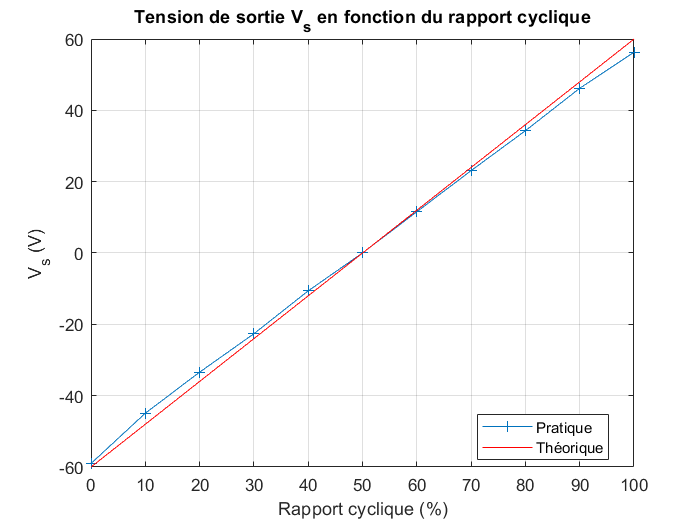

%%On prend la charge R=20 ohms pour Ps=180W
Ue=60;

alpha=[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];

Vs=[-59 -44.9 -33.4 -22.62 -10.6 0.031 11.57 23.11 34.3 46.2 56.3];
Ie=[0 2.48 1.41 0.67 0.2 0.07 0.22 0.69 1.44 2.57 3.77];
Is=[0 -3 -2.26 -1.52 -0.7 0.01 0.77 1.55 2.29 3.1 3.76];

Vsth=(2.*alpha-1)*Ue;

plot(alpha*100,Vs,'+-',alpha*100,Vsth,'r');
title("Tension de sortie V_s en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("V_s (V)");
grid on;
legend('Pratique','Théorique','Location','best');

On peut observer que l'allure de la courbe pratique est similaire à la courbe théorique.

Cette courbe est linéaire symétrique au point 0 (quand α=50%) puisque $V_S =\left(2\alpha -1\right)\times V_e$.

### 2) Ondulation de courant en commande bipolaire.

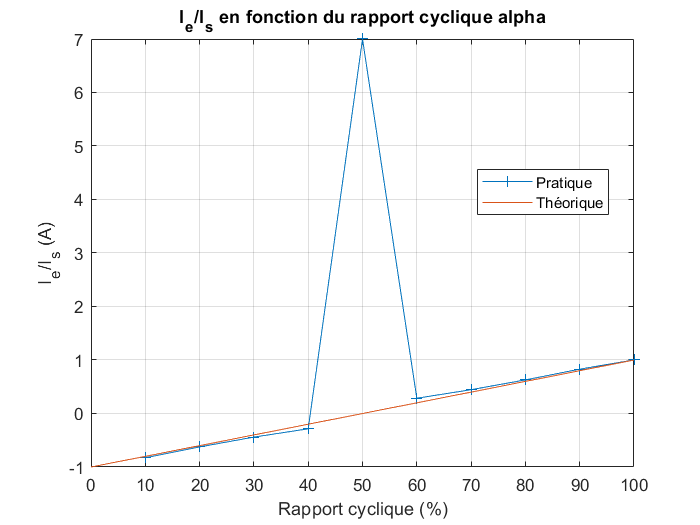

plot(alpha*100,Ie./Is,'+-',alpha*100,(2.*alpha-1));
title("I_e/I_s en fonction du rapport cyclique alpha");
xlabel("Rapport cyclique (%)"); ylabel("I_e/I_s (A)");
grid on;
legend('Pratique','Théorique','Location','best');

Sur cette courbe, on observe un pic à α=50%: pour rappel, sur la précedente courbe, on mesure Vs environ 0V pour ce rapport cyclique et puisque $I_S =\frac{V_S }{R}$, alors on trouve un Is proche de 0.

Théoriquement, nous devrions avoir un rapport nul, mais les transistors utilisés pour le bloc hacheur/onduleur consomment en permanence environ 0.6A. Le rapport Ie/Is est donc très grand pour ce rapport cyclique.

### 3) Ondulation de courant en commande unipolaire.

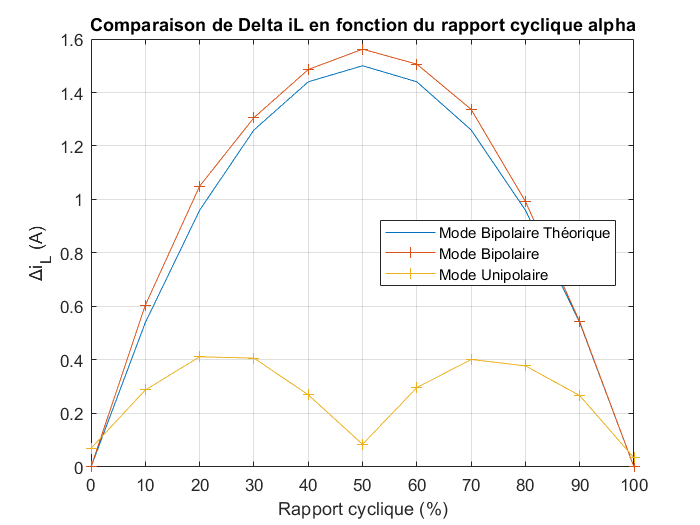

delta_iL_u=[70 288 412 407 270 85 297 402 378 267 34].*1e-3;%mA (Commande unipolaire)
delta_iL=[0 605 1050 1306 1486 1562 1506 1337 993 543 0 ].*1e-3;
L=2e-3; Fdec=10e3;
delta_iL_th=(2.*alpha.*Ue.*(1-alpha))./(L.*Fdec);
    
plot(alpha*100,delta_iL_th,alpha*100,delta_iL,'+-',alpha*100,delta_iL_u,'+-');
title("Comparaison de Delta iL en fonction du rapport cyclique alpha");
xlabel("Rapport cyclique (%)"); ylabel("Δi_L (A)");
grid on;
legend('Mode Bipolaire Théorique','Mode Bipolaire','Mode Unipolaire','Location','best');

On peut observer que la valeur maximale de l'ondulation de courant est bien plus importante pour une commande Bipolaire que pour une commande Unipolaire. 

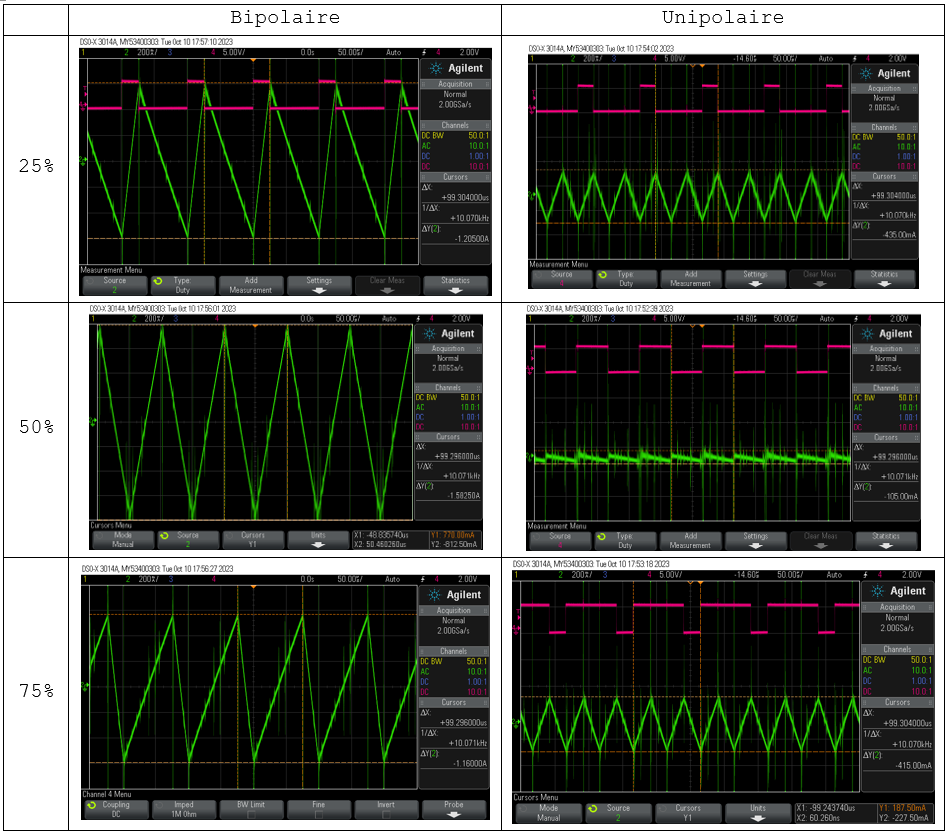

## 2/ Onduleur de tension monophasé à MLI

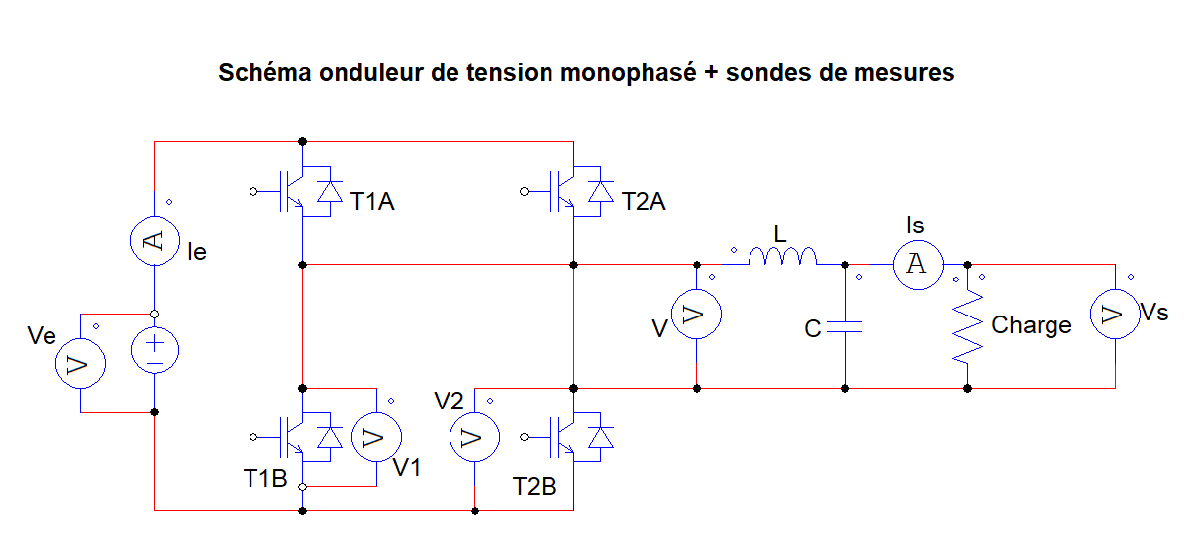

Afin d'avoir une puissance de sortie Ps de 80W, nous devons régler la charge R à 15$\Omega$ environ.

R=$\frac{{\textrm{Vs}}^2 }{\textrm{Ps}}$=$\frac{{35}^2 }{80}$=$15\ldotp 3\Omega$

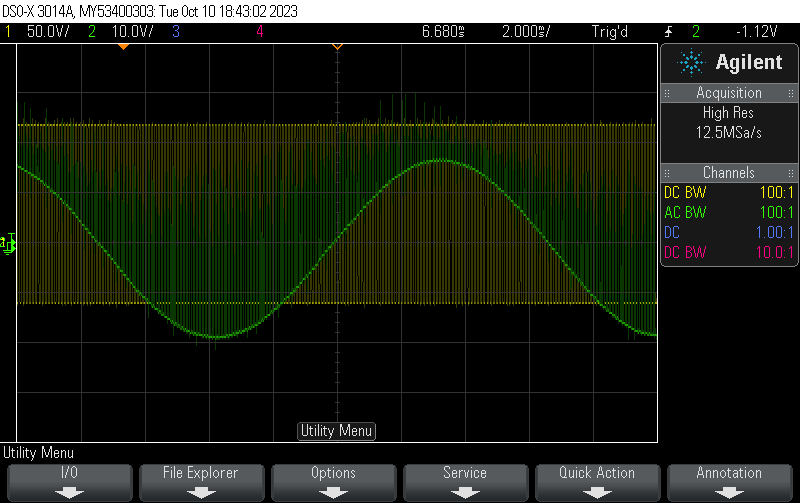

On observe qu'avant le filtre, la tension est carrée, tandis qu'après le filtre passe bas (LC), la tension est sinusoïdale. Si l'on zoom sur la courbe, on peut observer que cette courbe sinoïdale est constituée de charge et de décharge plus ou moins longue : c'est cette variation qui crée le signal sinusoidal.

La puissance moyenne fournie par la source est : $P_e =\frac{\textrm{Ve}}{\textrm{Ie}}=\frac{60V}{0\ldotp 28A}=16\ldotp 8W$.

La puissance moyenne absorbée par la charge est quand à elle : $P_s =\frac{\textrm{Us}\_\max /\sqrt{2}}{\textrm{Is}\_\textrm{Max}/\sqrt{2}}=\frac{19\ldotp 25/\sqrt{2}}{1\ldotp 35/\sqrt{2}}=12\ldotp 92W$.

Le rendement est donc : $\frac{\mathrm{Ps}}{\mathrm{Pe}}=\frac{12\ldotp 92}{16\ldotp 8}=0\ldotp 81$, soit 81%.

L'amplitude maximale possible pour $V_{\textrm{Seff}}$ est 60V si l'on considère m=1 et le rendement égal à 100%.

La **fréquence de découpage**, également appelée fréquence de commutation agit sur la rapidité avec laquelle les interrupteurs électroniques (transistors)  passent d'un état à l'autre pour moduler la tension de sortie : plus la fréquence est élevée, plus  le signal ressemblera à un sinus.

Faire varier la** fréquence de modulation **aura pour conséquence de faire varier la fréquence du signal sinusoïdal en sortie de l'onduleur.

Enfin, le** taux de modulation** agit sur l'amplitude de la tension de sortie : plus il est élevé, plus l'amplitude de sortie sera proche de la tension d'entrée ($V_e$). Pour rappel, $u_s =mU_e \sin \left(2\pi \textrm{ft}\right)$ avec m le taux de modulation, allant de 0 à 1. Faire varier m fera donc varier l'amplitude us.